# 第四次习题

## 阶梯

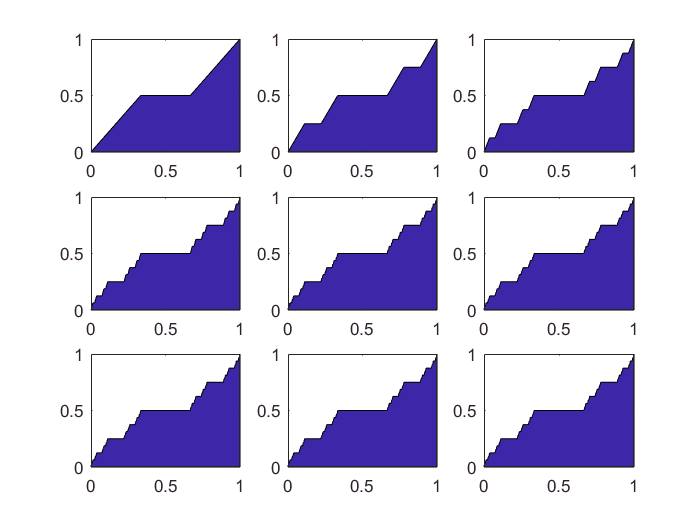

X = (0:3)/3; Y = [0, 1, 1, 2]/2;
figure;
subplot(3,3,1); area(X,Y);
for k = 2:9
    X = [X/3, X/3 + 2/3];
    Y = [Y/2, Y/2 + 1/2];
    subplot(3,3,k);
        area(X, Y)
end

## 分形方形

这里patch函数一般比fill快一些。

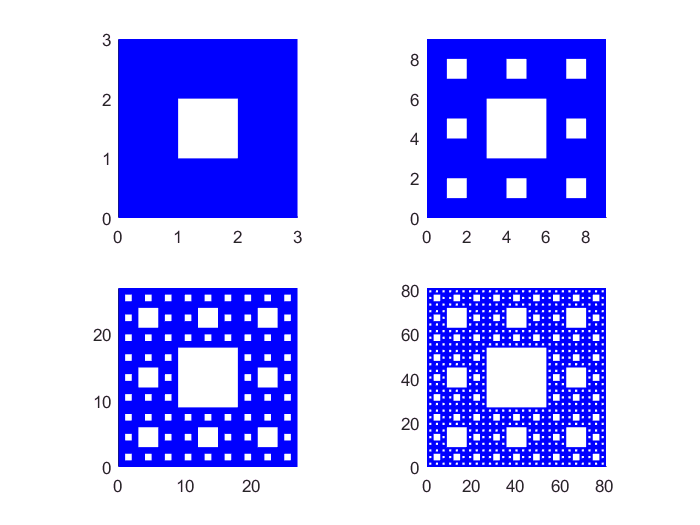

x = [0; 1; 1; 0; 0]; y = [0; 0; 1; 1; 0]; figure;
for k=1:4
    x = [x,x,x,x+3^(k-1),x+2*3^(k-1),x+2*3^(k-1),x+2*3^(k-1),x+3^(k-1)];
    y = [y,y+3^(k-1),y+2*3^(k-1),y+2*3^(k-1),y+2*3^(k-1),y+3^(k-1),y,y];
    subplot(2,2,k)
        patch(x,y,'b','edgecolor','none'); axis equal;
        xlim([0,max(max(x))]); ylim([0,max(max(y))]);
end

矩阵图像：

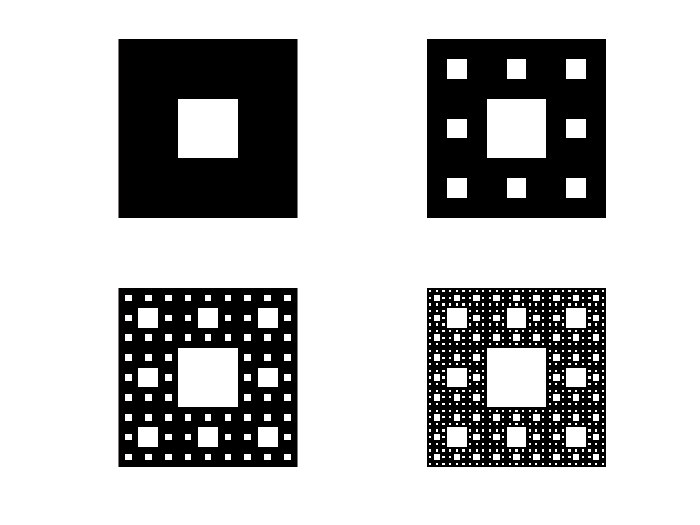

A = 0; figure;
for k = 1:4
    A = [A,     A,          A; ...
         A,    ones(size(A)),    A; ...
         A,     A,          A];
    subplot(2,2,k);
        imshow(A) % or use imagesc(A) and specify a colormap;
end

## 分形立方

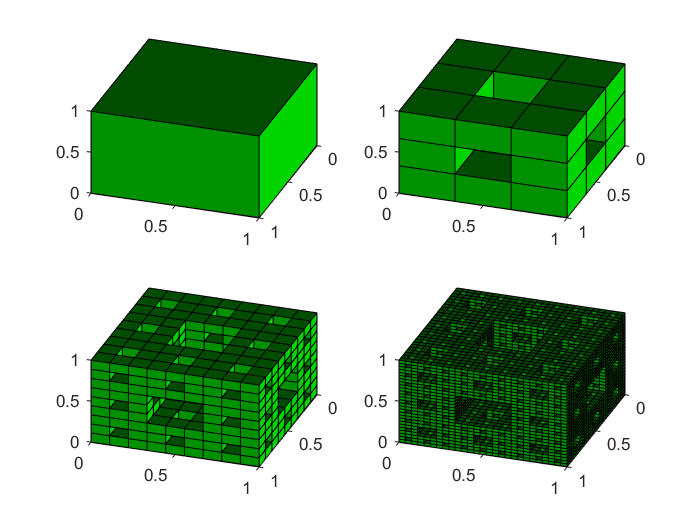

A=[0,0,0]; B=[1,0,0]; C=[1,1,0]; D=[0,1,0];
E=[0,0,1]; F=[1,0,1]; G=[1,1,1]; H=[0,1,1];

x = [A(1), B(1) ,C(1), D(1), A(1), E(1);
B(1), C(1) ,D(1), H(1), B(1), F(1);
F(1), G(1) ,H(1), E(1), C(1), G(1);
E(1), F(1) ,G(1), A(1), D(1), H(1)];

y = [A(2), B(2), C(2), D(2), A(2), E(2);
B(2), C(2), D(2), H(2), B(2), F(2);
F(2), G(2), H(2), E(2), C(2), G(2);
E(2), F(2), G(2), A(2), D(2), H(2)];

z = [A(3), B(3), C(3), D(3), A(3), E(3);
B(3), C(3), D(3), H(3), B(3), F(3);
F(3), G(3), H(3), E(3), C(3), G(3);
E(3), F(3), G(3), A(3), D(3), H(3)];

figure;

subplot(2, 2, 1)
    patch(x,y,z,'g'),
    view(109,43),light('Position',[1,2,0]); axis([0, 1, 0, 1, 0, 1]);

for k = 2:4
    x = x/3; x = [x,x,x,x+1/3,x+2*1/3,x+2*1/3,x+1/3,x+2*1/3,x,x+2*1/3,x,x+2*1/3,x,x,x,x+1/3,x+2*1/3,x+2*1/3,x+1/3,x+2*1/3];
    y = y/3; y = [y,y,y,y,y,y,y,y,y+1/3,y+1/3,y+1/3,y+1/3,y+2*1/3,y+2*1/3,y+2*1/3,y+2*1/3,y+2*1/3,y+2*1/3,y+2*1/3,y+2*1/3];
    z = z/3; z = [z,z+1/3,z+2*1/3,z,z,z+1/3,z+2*1/3,z+2*1/3,z,z,z+2*1/3,z+2*1/3,z,z+1/3,z+2*1/3,z,z,z+1/3,z+2*1/3,z+2*1/3];

    subplot(2, 2, k);
        patch(x, y, z, 'g');
        view(109, 43),light('Position', [1, 2, 0]);
end

全部用矩阵算速度更快一些：

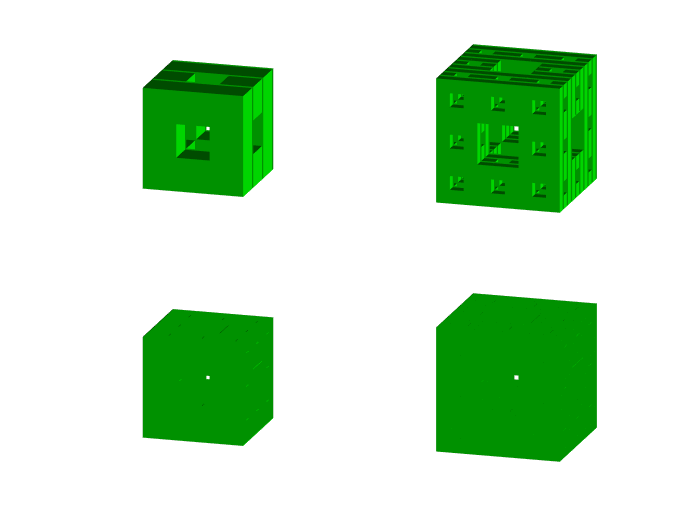

A = 0; figure;
for k = 1:4
    A = [A, A, A; A, ones(size(A)), A; A, A, A];
    B = reshape(repmat(A, 3^k, 1), [3^k, 3^k, 3^k]);
    C = permute(B, [1, 3, 2]); D = permute(B, [2, 3, 1]);
    E = B | C | D; E = ones(size(E)) - E;
    f = find(E == 1);
    x = ceil(f/9^k);
    y = ceil((mod(f - 1, 9^k) + 1)/3^k);
    z = mod((mod(f - 1, 9^k)), 3^k) + 1;
    P = reshape(repmat([x, y, z], 1, 8)', 3, 8*length(x))';
    V = [0 0 0; 0 1 0; 1 1 0; 1 0 0; 0 0 1; 0 1 1; 1 1 1; 1 0 1];
    V = P + repmat(V, length(x), 1);
    F = [1 2 3 4; 2 6 7 3; 4 3 7 8; 1 5 8 4; 1 2 6 5; 5 6 7 8];
    F = repmat(F, length(x), 1) + reshape(repmat(0:8:8*(length(x) - 1), 24, 1), [4, length(x)*6])';
    subplot(2,2,k);
        patch('Faces', F, 'Vertices', V, 'FaceColor', 'g', 'EdgeColor', 'none');
        axis equal; view([10,3,3]); axis off; light('Position', [10,20,0]);
end

% saveas(gcf, 'cube1.png')